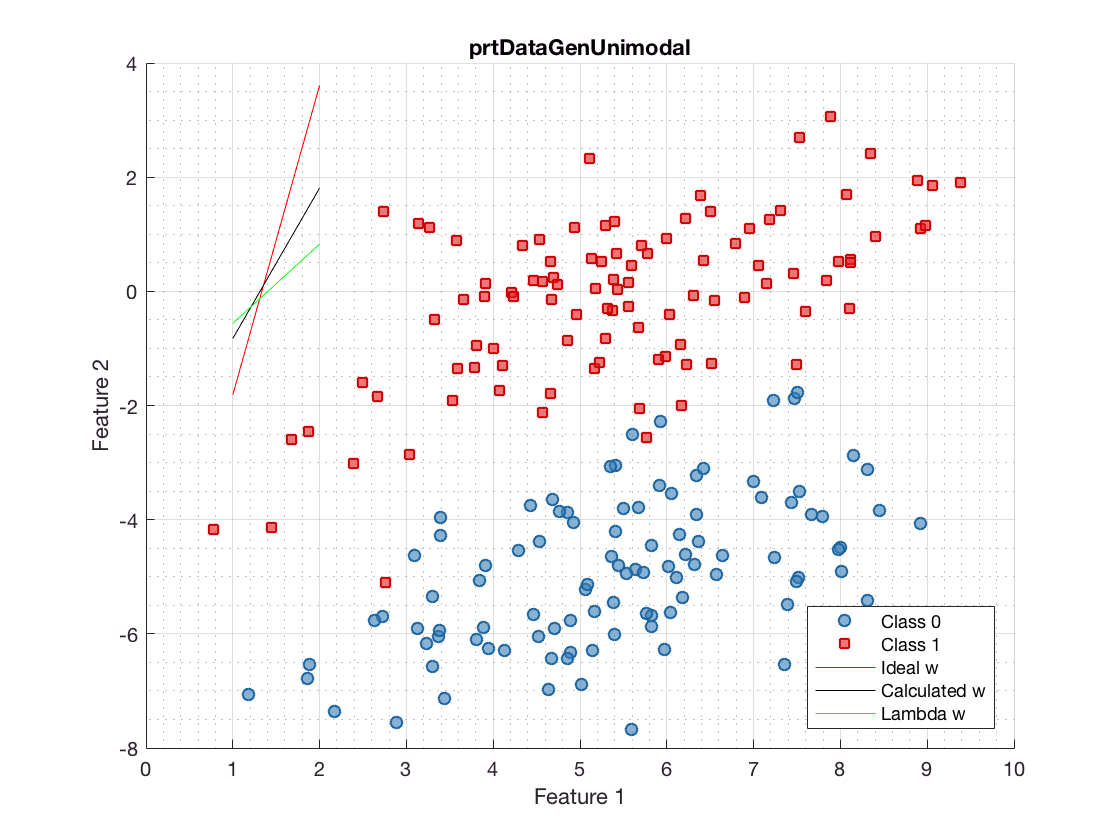

rng(2018)
r = rand(1,2)*2*pi;
%%below angles are in radians
theta_A = r(1,1);
theta_B = r(1,2);
%convert to degrees
theta_A = theta_A * (180 / pi);
theta_B = theta_B * (180 / pi);
%parameters
mu1 = [(5 / (tand(360 - theta_A))); 0];
mu0 = [(5 / (tand(360 - theta_A))); -5];
sigma1 = [cosd(theta_B), -sind(theta_B) ; sind(theta_B), cosd(theta_B)]*...
    [4,0;0,1]*[cosd(theta_B), -sind(theta_B); sind(theta_B), cosd(theta_B)]';
sigma0 = sigma1;

%ideal weight vector would be w = [((sigma1)^-1)*(mu1-mu0)]
idealw = [((sigma1)^-1)*(mu1-mu0)];

%create training dataset (dstrain)
dstrain = prtDataGenUnimodal(100,mu0,mu1,sigma0,sigma1);
plot(dstrain)
hold on
%Caculate new (non-ideal) w vector
dataH0 = dstrain.getObservationsByClassInd(1);
dataH1 = dstrain.getObservationsByClassInd(2);
x0 = mean(dataH0);
x1 = mean(dataH1);
Sw = cov(dataH0) + cov(dataH1);
Sb = (x1 - x0)*(x1 - x0)';
w = ((Sw)^-1)*(x1-x0)';
lambda = inv(Sw) * Sb;
[v,d] = eig(lambda);
wlambda = v(:,2);
plot(idealw,'r', 'DisplayName','Ideal w')
plot(w,'k', 'DisplayName','Calculated w')
plot(wlambda,'g', 'DisplayName','Lambda w')
hold off

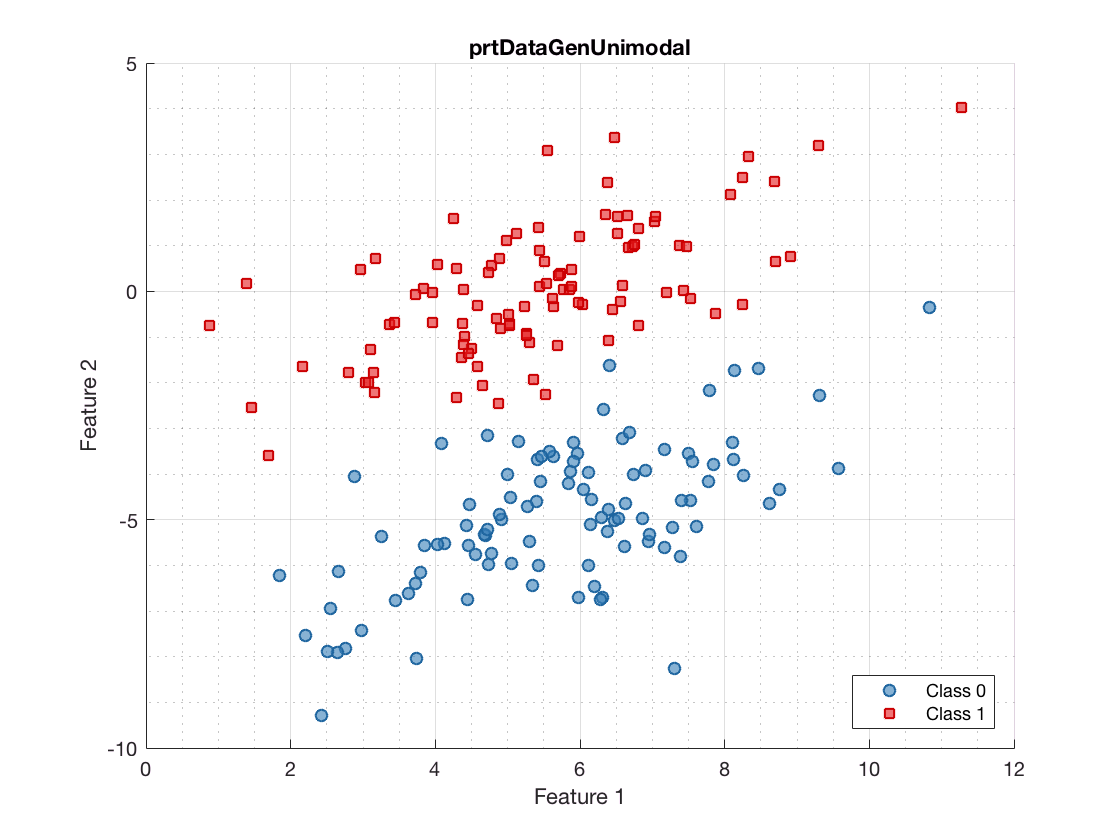


%create testing dataset (dstest)
dstest = prtDataGenUnimodal(100,mu0,mu1,sigma0,sigma1);
plot(dstest)


%Construct prtDataSetClass
X = dstrain.X;
Y = dstrain.Y;
scores = X*w;
dstrain_scores = prtDataSetClass(scores,Y);

%Train decider threshold
decider = prtDecisionBinaryMinPe;
decider_trained = decider.train(dstrain_scores);
threshold = decider_trained.threshold;

%Training set accuracy
X = dstrain.X;
Y = dstrain.Y;
dstrainscores = X*w;
dstrain_scores = prtDataSetClass(dstrainscores,Y);
results_dstrain = decider_trained.run(dstrain_scores);
prtScoreRoc(results_dstrain);
results_incestuous_dstrain = decider.rt(dstrain_scores);
hold on
prtScoreRoc(results_incestuous_dstrain);
Training_Set_Accuracy_w = prtScorePercentCorrect(results_incestuous_dstrain, dstrain)

Training_Set_Accuracy_w = 0.9900


%Testing set accuracy
X = dstest.X;
Y = dstest.Y;
scores = X*w;
dstest_scores = prtDataSetClass(scores,Y);
results = decider_trained.run(dstest_scores);
prtScoreRoc(results);
results_incestuous = decider.rt(dstest_scores);
prtScoreRoc(results_incestuous);
Testing_Set_Accuracy_w = prtScorePercentCorrect(results_incestuous,dstest)

Testing_Set_Accuracy_w = 0.9950

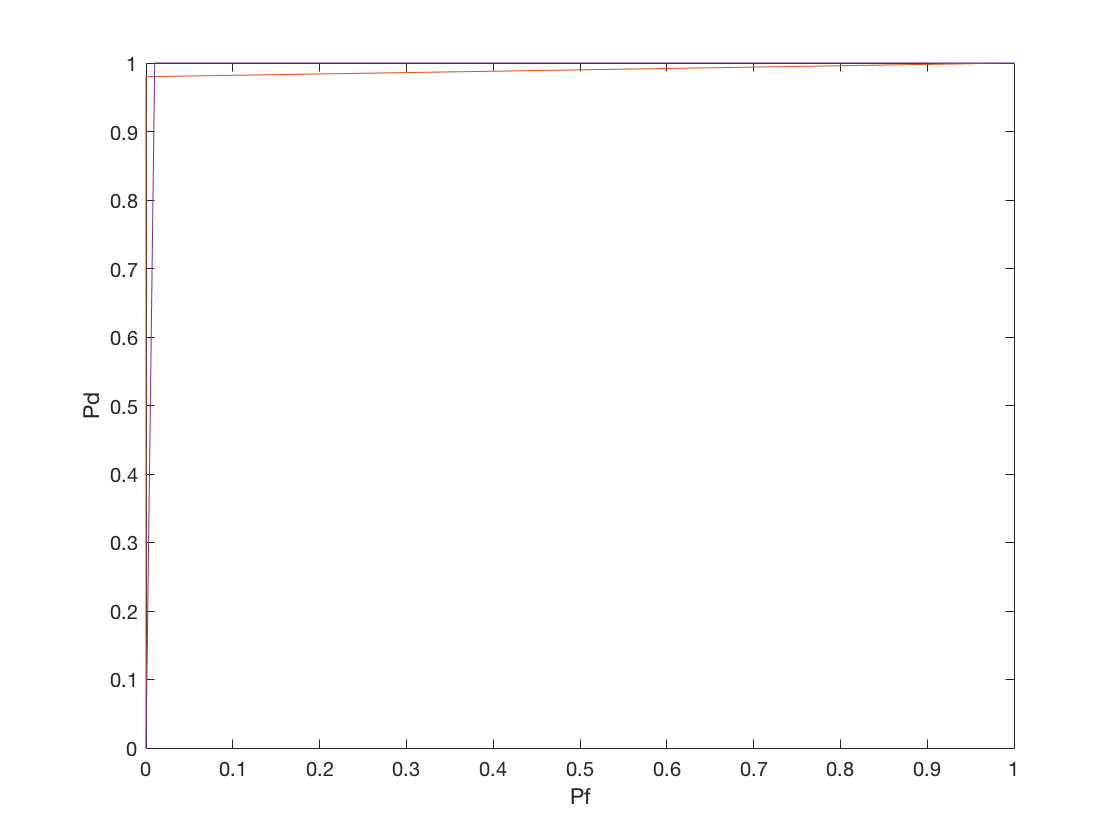

hold off

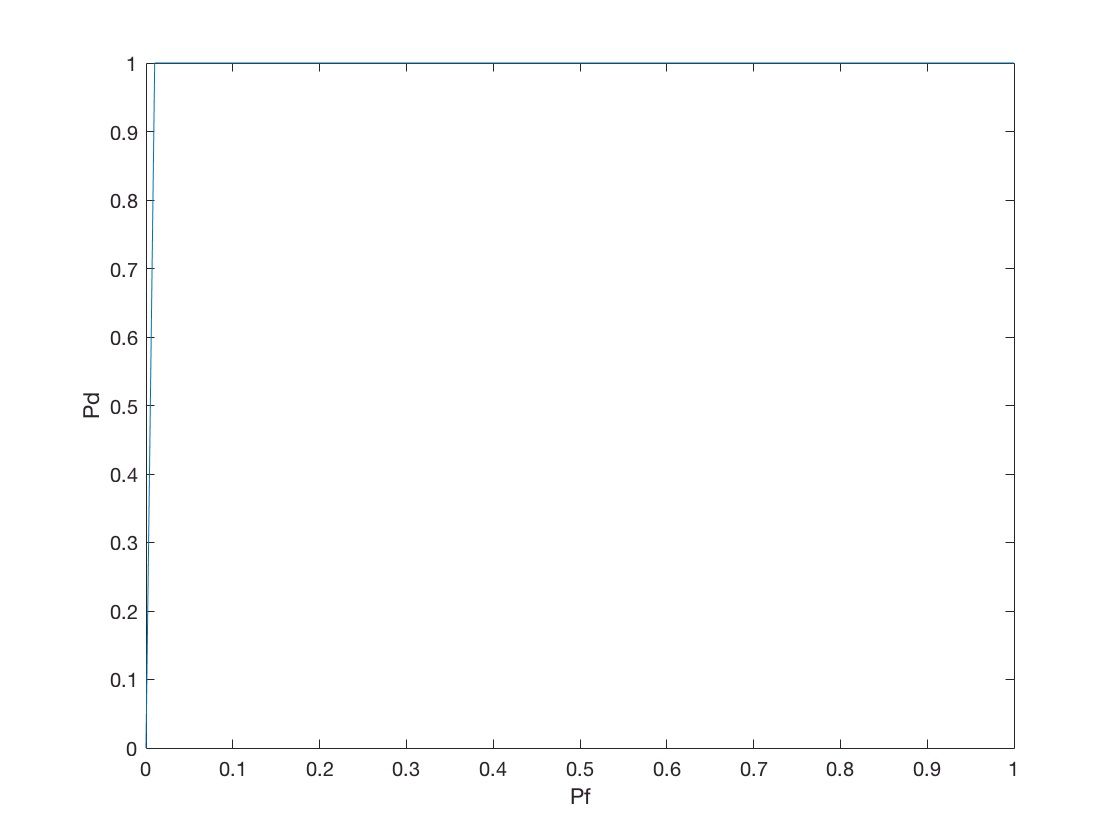


%Testing set accuracy with idealw
X = dstest.X;
Y = dstest.Y;
scores = X*idealw;
dstest_scores = prtDataSetClass(scores,Y);
results = decider_trained.run(dstest_scores);

%prtScoreRoc(results);
results_incestuous = decider.rt(dstest_scores);
prtScoreRoc(results_incestuous);

Testing_Set_Accuracy_idealw = prtScorePercentCorrect(results_incestuous,dstrain)

Testing_Set_Accuracy_idealw = 0.9950